# M-DOF system identification using the SSI-COV method

## Description of the model

The modal properties of a M-DOF system are identified by using the SSI-COV method. For this example, I am using simulated displacement records using a simple model of the Lysefjord bridge [1-3]. The displacement response has been simulated in five positions along the span. The goal is to estimate the modal frequencies, mode shapes and modal damping ratio using an automated covariance-driven stochastic subspace identification algorithm (SSI-COV) which is inspired by [4].

References:

[1] Cheynet, E., Jakobsen, J. B., & Snæbjörnsson, J. (2016).Buffeting response of a suspension bridge in complex terrain. Engineering Structures, 128, 474-487.

[2] Cheynet, E., Jakobsen, J. B., & Snæbjörnsson, J. (2017).Damping estimation of large wind-sensitive structures.Procedia engineering, 199, 2047-2053.

[3] Cheynet, E., Snæbjörnsson, J., & Jakobsen, J. B. (2017).Temperature Effects on the Modal Properties of a Suspension Bridge.In Dynamics of Civil Structures, Volume 2 (pp. 87-93). Springer, Cham.

[4] Magalhaes, F., Cunha, A., & Caetano, E. (2009). Online automatic identification of the modal parameters of a long span arch bridge. *Mechanical Systems and Signal Processing*, *23*(2), 316-329.

## Initialisation

Load simulated displacement data:

- *rz*: is the simulated vertical displacement response of the bridge in 5 positions along the span. It is a [5 x N] matrix

- *posSensors*: Is the position of the 5 sensors along the span. It is a [5 x 1] vector.

- *y*: Discrete span coordinates. It is a [Ny x 1] vector.

- *zetaStruct*: target modal damping ratios for the different modes of the structure. It is a [M x 1] vector.

- *phi*: target vertical mode shapes of the structure. It is a [M x 1] vector.

- *wn*: target vertical eigenmodes of the structure. It is a [M x 1] vector.

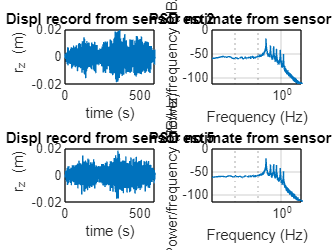

clearvars;close all;clc;
load('BridgeData.mat','t','rz','zetaStruct','phi','wn','posSensors','y')

fnTarget = wn/(2*pi); % transform circular frequency (rad/s) into frequency (Hz)
dt = median(diff(t)); % get time step
fs=1/dt; % get sampling freuqency
[Nyy,N]= size(rz); %Nyy is the number of sensors and N the number of time step

% Visualization of the data
clf;close all;
figure
subplot(221)
plot(t,rz(2,:))
xlim([0,600]);
xlabel('time (s)')
ylabel(' r_z (m)')
title('Displ record from sensor no 2')
subplot(222)
pwelch(rz(2,:),[],[],[],1/dt)
set(gca,'xscale','log')
title('PSD estimate from sensor no 2')
subplot(223)
plot(t,rz(5,:))
xlim([0,600]);
xlabel('time (s)')
ylabel(' r_z (m)')
title('Displ record from sensor no 5')
subplot(224)
pwelch(rz(5,:),[],[],[],1/dt)
set(gcf,'color','w')
set(gca,'xscale','log')
title('PSD estimate from sensor no 5')

## Application of SSI-COV

The model order fluctuates between "Nmin" and "Nmax". The function SSICOV automatically estimates the modal parameters of the system associated with the displacement history rz. The variable "paraplot" is used to plot the stabilization diagram.

tic
[fn0,zeta0,phi0,paraPlot] = SSICOV(rz,dt,'Ts',20,'Nmin',2,'Nmax',50);
toc

Elapsed time is 0.757675 seconds.


## Plot  the stabilization diagram

The PSD estimate of the displacement response at the position no. 2 is superposed to the the identified poles.

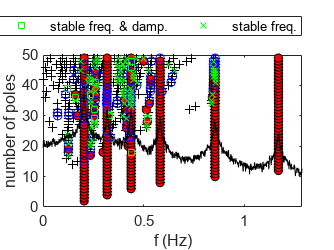

clf;close all;
[h] = plotStabDiag(paraPlot.fn,rz(2,:),fs,paraPlot.status,paraPlot.Nmin,paraPlot.Nmax);

## Visualization of the identified mode shapes

The six mode shapes are properly identified, as shown below:

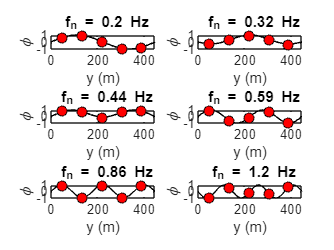

clf;close all;
figure
hold on

RMSE = @(y1,y2) sqrt(mean((y1-y2).^2));

clear ind
for ii=1:numel(fnTarget)
    subplot(3,2,ii)
    hold on;box on;
    plot(y,phi(ii,:),'k');
    [~,ind(ii)]=min(abs(fn0(ii)-fnTarget(1,:)));
    hold on;box on;
    
    
    % the identified mode shapes may have an opposite sign to the target mode shapes. 
    % This issue is corected by comparing the root-mean square error between the target and identified mode shapes.
    [~,indPos] = intersect(y,posSensors);
    if RMSE(phi(ii,indPos),phi0(ind(ii),:))>RMSE(phi(ii,indPos),-phi0(ind(ii),:)),
        plot(posSensors,-phi0(ind(ii),:),'ko','markerfacecolor','r')
    else
        plot(posSensors,phi0(ind(ii),:),'ko','markerfacecolor','r')
    end
    
    xlabel('y (m)')
    ylabel('\phi');
    title([' f_n = ',num2str(nanmean(fnTarget(:,ii)),2),' Hz'])
    axis tight
    ylim([-1,1])
end

set(gcf,'color','w')

## Comparison of the identified and target modal damping ratios

It is in general challenging to identify the modal damping ratios from ambient vibrations data. Therefore the agreement between the estimated and target modal damping ratios is here good.

T1 = table(zetaStruct(:),(round(zeta0(ind).*1e4)/1e4)','VariableNames',{'Target','Estimate'});
disp(T1)

    Target    Estimate
    ______    ________

    0.005      0.0049 
    0.005      0.0059 
    0.005      0.0062 
    0.005      0.0055 
    0.005      0.0057 
    0.005      0.0041 



## Comparison of the identified and target eigenfrequencies

The small discrepancies at higher frequencies between the identified and target eigenfrequencies do not come from the SSI-COV algorithm. They come from the numerical scheme used for the time-domain simulation of the bridge response, which relies on the Newmark-beta method. 

T2 = table((round(fnTarget(:).*1e3)/1e3),(round(fn0(ind).*1e3)/1e3)','VariableNames',{'Target','Estimate'});
disp(T2)

    Target    Estimate
    ______    ________

    0.205      0.205  
    0.319      0.319  
    0.439      0.438  
    0.585      0.582  
    0.864      0.855  
    1.194      1.171  

